clear all

syms cc
taylor(exp(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{120}+\frac{{\mathrm{cc}}^{4}}{24}+\frac{{\mathrm{cc}}^{3}}{6}+\frac{{\mathrm{cc}}^{2}}{2}+\mathrm{cc}+1$$

taylor(sin(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{120}-\frac{{\mathrm{cc}}^{3}}{6}+\mathrm{cc}$$


taylor(exp(cc)) + taylor(sin(cc))+3*taylor(cos(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{60}+\frac{{\mathrm{cc}}^{4}}{6}-{\mathrm{cc}}^{2}+2\,\mathrm{cc}+4$$

input = 2*rand(1000,1)-1;
output = sin(exp(input)+sin(10*input).^2+3*cos(3*input)+0.3*rand(1000,1));

% output= (output-mean(output))/std(output);

output = normalize(output);


datasize = length(input);
batchsize = 100;
minis = datasize/batchsize

minis = 10

decay =0.9999

decay = 0.9999

alpha = 0.00001

alpha = 1.0000e-05

alfa = 0.001

alfa = 1.0000e-03

beta= 0

beta = 0

n=4

n = 4

eps = 10^-2

eps = 0.0100


V=zeros(batchsize,1) %momentum

V =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


B = 0.9

B = 0.9000

V1=0;
V2=0;
V3=0;
V4=0;

X = normalize(rand(n+1,4))/10;
ex= [0:n];

w1= X(:,1);
w2= X(:,2);
w3= X(:,3);



err(1:2)=1;
alfa = 0.0001

alfa = 1.0000e-04

% number of epochs
for i = 2:1000

% Learning rate
alpha=alfa %/(eps+err(i));  
alphas(i)=alpha;    
    
%divide data in batches
indexes= randperm(1000);
batchinput = reshape(input(indexes), [batchsize minis]);    
batchoutput = reshape(output(indexes), [batchsize minis]);

    for j = 1:minis
a1 = batchinput(:,j);
a2 = normalize(a1.^ex*w1);
a3 = normalize(a2.^ex*w2);
a4 = (a3.^ex*w3);

% meansa2(j) = mean(a2);
% meansa3(j) = mean(a3);
% stdsa2(j) = std(a2);
% stdsa3(j) = std(a3);
% a4 = a3.^ex*w3;
% % d4 = a4-batchoutput(:,j);
% d3 = d4 .* [zeros(batchsize,1) ones(batchsize,1) 2*a3 3*a3.^2 4*a3.^3] *w3;

d4 = a4-batchoutput(:,j);
grad3 = gradidi(a3,n);
grad2 = gradidi(a2,n);
grad1 = gradidi(a1,n);
d3 = d4 .* grad3 *w3;
d2 = d3 .* grad2 *w2;
d1 = d2 .* grad1 *w1;

% D = [d2;d1]

V4=B*V4 + (1-B)*d4;
V3=B*V3 + (1-B)*d3;
V2=B*V2 + (1-B)*d2;
V1=B*V1 + (1-B)*d1;

w3 = pinv((a3-beta*alpha*V3).^ex)*(a4-alpha*V4)*decay;
w2 = pinv((a2-beta*alpha*V2).^ex)*(a3-alpha*V3)*decay;
w1 = pinv((a1).^ex)*(a2-alpha*(V2))*decay;

    end

a1=input;
a2 = a1.^ex*w1;
a3 = a2.^ex*w2;
a4 = a3.^ex*w3;

err(i+1) = norm(a4-output)/norm(output);

if (err(i)<0.0001) ||(abs(err(i)-err(i-1))<0.0000001)
    disp("iterations: " + i)
     disp("error: " + err(i))
    break;
end 
end

alpha = 1.0000e-04

iterations: 2


error: 1


disp("error: " + err(i))

error: 1


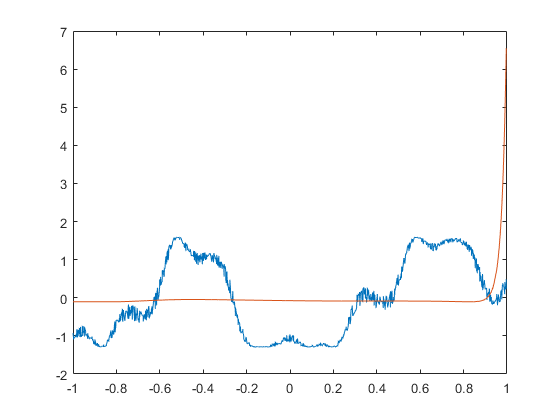


[B1,I] = sort(input);
B2 = output(I);

plot([B1 B1],[B2 a4(I)])

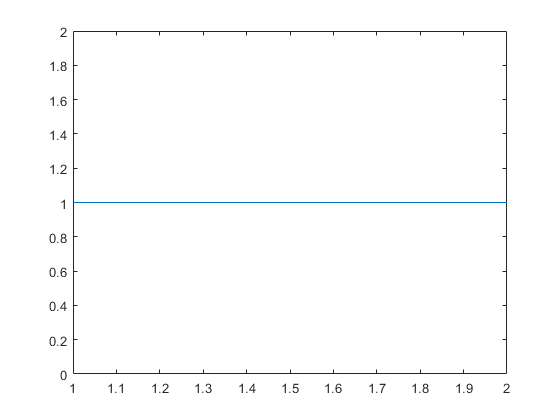


plot(err(1:i))

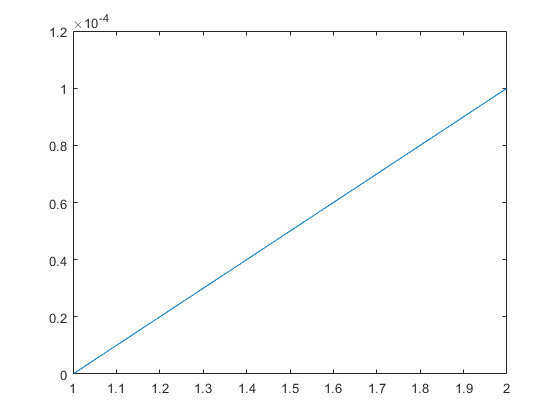

plot(alphas(1:i))


w1

w1 =    -0.3522
   -1.3071
    2.5922
   -0.3012
   -2.2927


w2

w2 =     0.6198
    0.3089
   -0.2002
    0.1698
   -0.2092


w3

w3 =    -0.1043
    0.0231
    0.1117
   -0.1040
    0.0738



ex=0:3

ex =      0     1     2     3


% zeros(1000,1) ones(1000,1)

w1 =  rand(4,1)

w1 =     0.0993
    0.3685
    0.5135
    0.3801


w2 =  rand(4,1)

w2 =     0.0017
    0.7176
    0.3451
    0.6564



a1 = input(1:200)

a1 =     0.4451
   -0.9948
   -0.5888
   -0.4793
   -0.8401
    0.4707
    0.6453
   -0.3132
   -0.7277
    0.3318



a2 = a1.^ex*w1 

a2 =     0.3986
   -0.1333
   -0.0173
   -0.0012
   -0.0732
    0.4261
    0.6530
    0.0225
   -0.0434
    0.2919



a3 = a2.^ex*w2

a3 =     0.3841
   -0.0894
   -0.0106
    0.0008
   -0.0493
    0.4209
    0.8002
    0.0181
   -0.0289
    0.2569




d3 = a3-output(1:200)

d3 =     0.4407
    0.9478
   -0.6658
   -1.3522
    1.0454
    0.3581
   -0.6229
   -0.8625
    0.1845
    0.3099


d2 = d3 .* [zeros(200,1) ones(200,1) 2*a2 3*a2.^2] *w2

d2 =     0.5753
    0.6261
   -0.4703
   -0.9692
    0.7084
    0.4903
   -1.2509
   -0.6332
    0.1275
    0.3368


d1 = d3 .* [zeros(200,1) ones(200,1) 2*a1 3*a1.^2] *w1

d1 =     0.4634
    0.4503
   -0.1059
   -0.1868
    0.3245
    0.3955
   -0.9382
   -0.1368
    0.0415
    0.2587



w2 = pinv([a2-0.01*d2].^ex)*[a3-0.1*d3]*0.999

w2 =    -0.0247
    0.7489
    0.0153
    1.0974


w1 = pinv(a1.^ex)*[a2-0.01*d2]*0.999

w1 =     0.1048
    0.3917
    0.4677
    0.3043



% ---------
a2 = a1.^ex*w1;

a3 = a2.^ex*w2;

C = 0.5*(a3-output(1:200)).^2;
norm(C)/norm(output(1:200))

ans = 0.9777

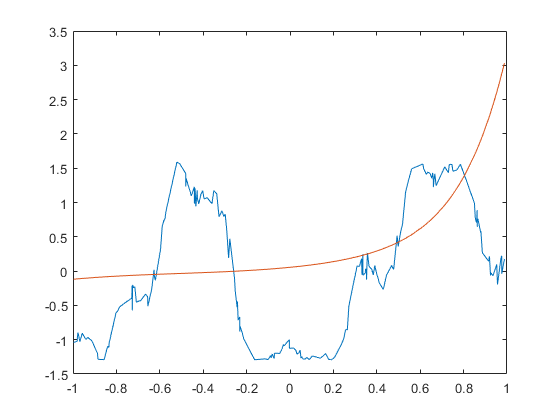




[B1,I] = sort(input(1:200));
B2 = output(I);

plot([B1 B1],[B2 a3(I)])


w1

w1 =     0.1048
    0.3917
    0.4677
    0.3043


w2

w2 =    -0.0247
    0.7489
    0.0153
    1.0974


ex= 0:10

ex =      0     1     2     3     4     5     6     7     8     9    10


newin = input

newin =     0.4451
   -0.9948
   -0.5888
   -0.4793
   -0.8401
    0.4707
    0.6453
   -0.3132
   -0.7277
    0.3318


newout = output

newout =    -0.0566
   -1.0372
    0.6553
    1.3530
   -1.0947
    0.0628
    1.4232
    0.8805
   -0.2133
   -0.0530



[B1,I] = sort(newin);

newin(I(200:700))=[]

newin =     0.4451
   -0.9948
   -0.8401
    0.4707
    0.6453
   -0.7277
    0.6609
   -0.7211
    0.9561
    0.7338


newout(I(200:700))=[]

newout =    -0.0566
   -1.0372
   -1.0947
    0.0628
    1.4232
   -0.2133
    1.2250
   -0.2429
   -0.1945
    1.5529



newin.^ex

ans =     1.0000    0.4451    0.1981    0.0882    0.0393    0.0175    0.0078    0.0035    0.0015    0.0007    0.0003
    1.0000   -0.9948    0.9896   -0.9845    0.9794   -0.9743    0.9692   -0.9641    0.9591   -0.9541    0.9492
    1.0000   -0.8401    0.7058   -0.5929    0.4981   -0.4184    0.3515   -0.2953    0.2481   -0.2084    0.1751
    1.0000    0.4707    0.2215    0.1043    0.0491    0.0231    0.0109    0.0051    0.0024    0.0011    0.0005
    1.0000    0.6453    0.4164    0.2687    0.1734    0.1119    0.0722    0.0466    0.0301    0.0194    0.0125
    1.0000   -0.7277    0.5296   -0.3854    0.2805   -0.2041    0.1485   -0.1081    0.0787   -0.0572    0.0417
    1.0000    0.6609    0.4368    0.2887    0.1908    0.1261    0.0833    0.0551    0.0364    0.0241    0.0159
    1.0000   -0.7211    0.5200   -0.3749    0.2704   -0.1949    0.1406   -0.1014    0.0731   -0.0527    0.0380
    1.0000    0.9561    0.9141    0.8740    0.8357    0.7990    0.7639    0.7304    0.6983    0.6677    0.

www = pinv(newin.^ex)*(newout);

I(200:700)=[]

I =    857
   263
    55
     2
   411
   396
   542
   959
   127
   507


B2 = newout(I);

Index exceeds the number of array elements (499).


recon = input.^ex*www


plot([B1 B1],[B2 recon(I)])

rataa = norm(recon-newout)/norm(newout)
